# 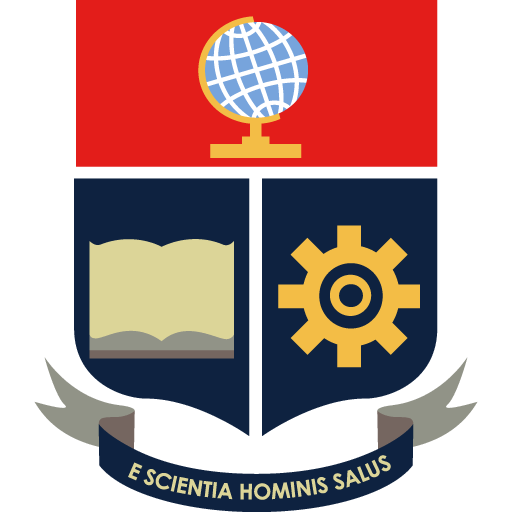Escuela Politécnica Nacional

#### `UTILIZACIÓN DEL SISTEMA DE RECONOCIMIENTO DE GESTOS EMPLEADO EN EL PROYECTO DE INVESTIGACIÓN PIGR-19-07 PARA EL COMANDO DE UN SISTEMA MULTI-AGENTE`

*Se disponen de dos pruebas cuando se posee 1 agente:*

- Prueba de control de trayectoria para llegar a una posición

- Prueba de movimiento de un agente con la IMU (señales inerciales) del sensor Myo Armband

`Ir a:`
`Prueba de trayectoria a la posición
``Prueba de movimiento con la IMU`

# **Prueba de trayectoria a la posición**

En esta sección se comprueba el control realizado para que un robot realice una trayectoria en línea recta, para lo cual primero cambia su orientación en el mismo sitio, y para que el robot mantenga una velocidad lineal proporcional a la dirección de la meta

El robot seguirá la posición del lider vitural por en encima en el eje Y:

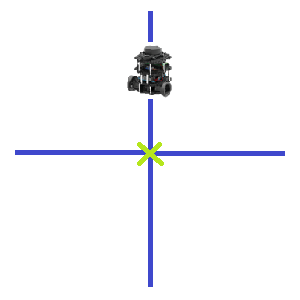

Ingrese el dato de la posición para el lider virtual (inicial: 0,0):

x=-0.5;
y=0;

%Se toma como posición central al lider virtual: (0,0)
rx1=0; ry1=d;%Pos del agente referenciado al lider virtual
a=2;
 

- En la máquina virtual debe estar abierta la escena para One_Robot

- Una vez termina la prueba cierre la simulación en el terminal emergente que da esa opción

 
%Movimiento angular y lineal junto
clc
disp("Simulación iniciada")

Simulación iniciada


sim("OneRobot1.slx");
disp("Simulación terminada en:")

Simulación terminada en:


time1=simtime(length(simtime));
fprintf("Tiempo = %.2f segundos\n",time1)

Tiempo = 62.58 segundos


time1ROS=rostime(length(rostime))-rostime(1);
fprintf("Tiempo ROS = %.2f segundos\n",time1ROS)

Tiempo ROS = 10.73 segundos


PosX1_1=PosX1;
PosY1_1=PosY1;
while PosX1_1(1)==0
    PosX1_1(1)=[];
    PosY1_1(1)=[];
end

- En la máquina virtual escoja nuevamente la escena para One_Robot para realizar la prueba en las misma condiciones, en este caso aplicando control condicional

- Una vez termina la prueba cierre la simulación en el terminal emergente que da esa opción


 
%Orientación y luego trayectoria recta
clc
disp("Simulación iniciada")

Simulación iniciada


sim("OneRobot.slx");
disp("Simulación terminada en:")

Simulación terminada en:


time2=simtime(length(simtime));
fprintf("Tiempo = %.2f segundos\n",time2)

Tiempo = 65.43 segundos


time2ROS=rostime(length(rostime))-rostime(1);
fprintf("Tiempo ROS = %.2f segundos\n",time2ROS)

Tiempo ROS = 9.32 segundos


PosX1_2=PosX1;
PosY1_2=PosY1;
while PosX1_2(1)==0
    PosX1_2(1)=[];
    PosY1_2(1)=[];
end

- En la máquina virtual escoja nuevamente la escena para One_Robot para realizar la prueba en las misma condiciones, con control proporcional


 
%Orientación y trayectoria proporcional
clc
disp("Simulación iniciada")

Simulación iniciada


sim("OneRobot_proporcional.slx");
disp("Simulación terminada en:")

Simulación terminada en:


time3=simtime(length(simtime));
fprintf("Tiempo = %.2f segundos\n",time3)

Tiempo = 38.97 segundos


time3ROS=rostime(length(rostime))-rostime(1);
fprintf("Tiempo ROS = %.2f segundos\n",time3ROS)

Tiempo ROS = 9.69 segundos


PosX1_3=PosX1;
PosY1_3=PosY1;
while PosX1_3(1)==0
    PosX1_3(1)=[];
    PosY1_3(1)=[];
end

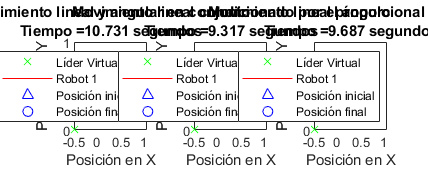

 
clc
f=figure;
subplot(1,3,1)
plot(x,y,'gx')
hold on
plot(PosX1_1,PosY1_1,'r')
plot(PosX1_1(1),PosY1_1(1),'b^')
plot(x+rx1,y+ry1,'bo')
limitex=xlim;%([-0.5 1.5]) 
limitey=ylim;%([0 1])
tiempotit=strcat('Tiempo = ',num2str(time1ROS),' segundos');
% dim=[.1 .8 .3 .3];
% str = {'Tiempo de simulación = ',strcat(num2str(time1),' segundos')};
% annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
title({"Movimiento lineal y angular en conjunto";tiempotit})
xlabel('Posición en X')
ylabel('Posición en Y')
legend('Líder Virtual','Robot 1','Posición inicial','Posición final','Location','southeast')

subplot(1,3,2)
plot(x,y,'gx')
hold on
plot(PosX1_2,PosY1_2,'r')
plot(PosX1_2(1),PosY1_2(1),'b^')
plot(x+rx1,y+ry1,'bo')
xlim(limitex);
ylim(limitey);
% dim=[.41 .8 .3 .3];
% str = {'Tiempo de simulación = ',strcat(num2str(time2),' segundos')};
% annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
tiempotit=strcat('Tiempo = ',num2str(time2ROS),' segundos');
title({"Movimiento lineal condicionado por el ángulo"; tiempotit})
xlabel('Posición en X')
ylabel('Posición en Y')
legend('Líder Virtual','Robot 1','Posición inicial','Posición final','Location','southeast')

subplot(1,3,3)
plot(x,y,'gx')
hold on
plot(PosX1_3,PosY1_3,'r')
plot(PosX1_3(1),PosY1_3(1),'b^')
plot(x+rx1,y+ry1,'bo')
xlim(limitex);
ylim(limitey);
% dim=[.7 .8 .3 .3];
% str = {'Tiempo de simulación = ',strcat(num2str(time3),' segundos')};
% annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
tiempotit=strcat('Tiempo = ',num2str(time3ROS),' segundos');
title({"Movimiento lineal proporcional al ángulo"; tiempotit})
xlabel('Posición en X')
ylabel('Posición en Y')
legend('Líder Virtual','Robot 1','Posición inicial','Posición final','Location','southeast')
f.Position(3:4) = [1062.4 420];
f.Position(1:2) = [0 350];

.

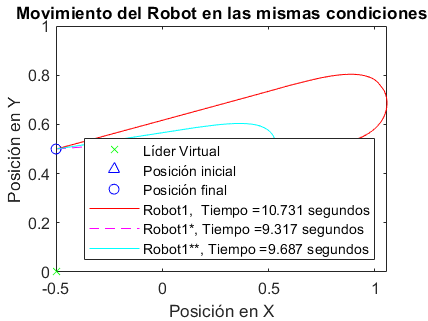

f2=figure;
plot(x,y,'gx')
hold on
plot(PosX1_1(1),PosY1_1(1),'b^')
plot(x+rx1,y+ry1,'bo')
plot(PosX1_1,PosY1_1,'r')
tiempotit1=strcat('Robot1,  Tiempo = ',num2str(time1ROS),' segundos');
hold on
plot(PosX1_2,PosY1_2,'m--')
plot(PosX1_3,PosY1_3,'c')
% xlim([-0.5 1.5]) 
% ylim([0 1])
% str = {'Tiempo de simulación: ',strcat(num2str(time1),' segundos'),strcat(num2str(time2),' segundos'),strcat(num2str(time3),' segundos')};
% annotation('textbox',[.15 .6 .3 .3],'String',str,'FitBoxToText','on','LineStyle','none');
tiempotit2=strcat('Robot1*, Tiempo = ',num2str(time2ROS),' segundos');
tiempotit3=strcat('Robot1**, Tiempo = ',num2str(time3ROS),' segundos');
title('Movimiento del Robot en las mismas condiciones')
xlabel('Posición en X')
ylabel('Posición en Y')
legend('Líder Virtual','Posición inicial','Posición final',tiempotit1,tiempotit2,tiempotit3,'Location','southeast')
f2.Position(1:2) = [278 340];

`Ir a:`

`Prueba de trayectoria a la posición
``Prueba de movimiento con la IMU`

# **Prueba de movimiento con la IMU**

Seguir los siguientes pasos:

- Colocarse el sensor

- Ejecutar el archivo correspondiente para comados según el caso en la otra instancia de MATLAB. Para terminar la prueba realizar el gesto "open" o ingresar el comando de referencia correspondiente (4), 

 
%pause(0.1);
if ind2==1
install_myo_mex; % adds directories to MATLAB search path
% install_myo_mex save % additionally saves the path
sdk_path = 'C:\myo-sdk-win-0.9.0'; % root path to Myo SDK
build_myo_mex(sdk_path); % builds myo_mex
ind2=2;
end

vectorx=[];
vectory=[];
posicionx1=[];
posiciony1=[];
T_imu=[];
euAng=[];
i=1;
j=1;
k=1;
while option ~=4
%lectura del gesto
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    switch option
        case 1
            gesim="1.png";gesto="Gesto - Wave out";
        case 2
            gesim="2.png";gesto="Gesto - Wave in";
        case 3
            gesim="3.png";gesto="Gesto - Fist";
        case 4
            gesim="4.png";gesto="Gesto - Open";
        case 5
            gesim="5.png";gesto="Gesto - Pinch";
        otherwise
            gesim="6.png";gesto="Relajado - No Gesture";
    end
    end
    %fin de lectura del gesto

run movimiento.m
run moving.m

tiempo=simtime(length(simtime));
printStatus(tiempo,ind)
ind=2;

vectorx(i)=x;
vectory(i)=y;
i=i+1;
for jj=1:length(PosX1)
posicionx1(j)=PosX1(jj);
posiciony1(j)=PosY1(jj);
j=j+1;
end
for kk=1:length(timeIMU)
T_imu(k)=timeIMU(kk);
euAng(k)=eulerAngles(kk);
k=k+1;
end


pause(0.1);%probar cambiando y ponerlo en el escrito
%fin de contenido de while
end


Inicio de toma de datos
In Yaw limits
In Pitch limits
Fuera



vectrx1=vectorx+rx1*ones(length(vectorx));
vectry1=vectory+ry1*ones(length(vectory));

figure;
        subplot(1,2,1)
        plot(vectorx,vectory,'gx')
        hold on
        plot(posicionx1,posiciony1,'r')
        plot(vectrx1,vectry1,'bo')
        xlabel('Posicion en X')
        ylabel('Posicion en Y')
        legend('Lider Virtual','Robot 1','Posición 1')
        title('Movimiento realizado')

        subplot(1,2,2)
        plot(T_imu,euAng); title('Ángulos Euler realizados'); legend('yaw','pitch','roll');

disp("Fin de prueba de Movimiento")


function printStatus (mssg,ind)
     if ind == 1
         % The very first time we don't need to delete the old text
         fprintf('Simulación terminada en: %.2f', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bSimulación terminada en: %.2f', mssg);
     end
end